clc;
clear;

data = 'free_space';
contact = 'no_contact';
test_folder = 'test';
rnn = 'lstm';
network = '_seal_pred_filtered_torque_glove_1_15.csv';

arm = 'psm1_mary';

%loss = 0;
loss = [0,0,0,0];

%for file = 0:3
file = 0;
exp = ['exp',num2str(file)];

% joint_path = ['../../glove_jan_10/', test_folder, '/', arm, '/', data, '/joints/'];
%       torque_path = ['../../glove_jan_10/', test_folder, '/', arm, '/', data, '/', 'lstm', network];
      
% joint_path = ['../../../simon_trocar_feb_27/test', '/joints/'];
% fs_pred_torque_path = ['../../../simon_trocar_feb_27/test', '/TO_free_comp_model_pred.csv'];
% troc_corr_path = ['../../../simon_trocar_feb_27', '/filtered_corrected_torque_prediction.csv'];

joint_path = ['../../simon_trocar_mar_6/free_space_needle', '/joints/'];
fs_pred_torque_path = ['../../simon_trocar_mar_6/free_space_needle', '/TO_cont_model_pred.csv'];
troc_corr_path = ['../../simon_trocar_mar_6/fs_needle_NN_train/train', '/lstm_pred_filtered_torque.csv'];
      

joint_data = readmatrix([joint_path, 'interpolated_all_joints_CUT.csv']);
fs_pred_data = readmatrix(fs_pred_torque_path);
troc_corr_data = readmatrix(troc_corr_path);

measured_torque = joint_data(:,14:16);
fs_pred_torque = fs_pred_data(:,1:3);

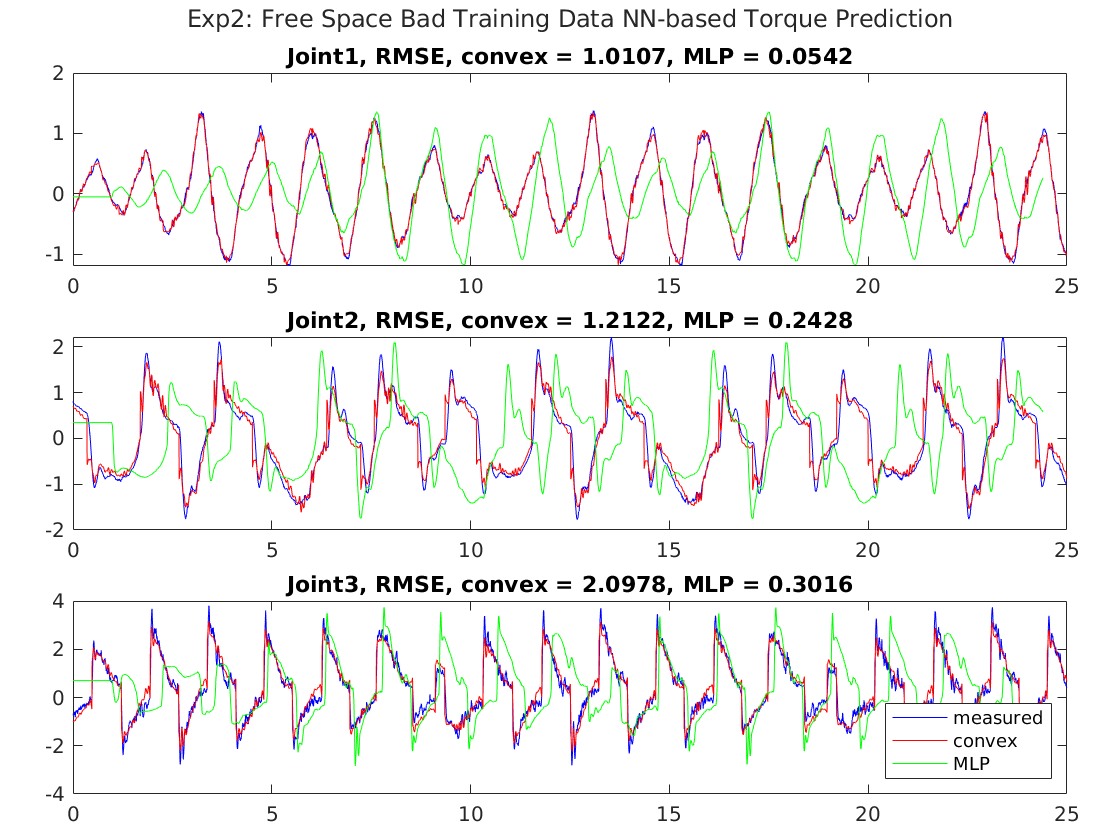

troc_cor = troc_corr_data(:,2:4);

% loss(file+1) = mean(sqrt(mean((measured_torque(1:length(troc_cor),:) - fs_pred_torque).^2)));
loss_joint1 = mean(sqrt(mean((measured_torque(1:length(troc_cor),1) - troc_cor(:,1)).^2)));
loss_joint2 = mean(sqrt(mean((measured_torque(1:length(troc_cor),2) - troc_cor(:,2)).^2)));
loss_joint3 = mean(sqrt(mean((measured_torque(1:length(troc_cor),3) - troc_cor(:,3)).^2)));
loss_joint1_fs = mean(sqrt(mean((measured_torque(1:length(fs_pred_torque),1) - fs_pred_torque(:,1)).^2)));
loss_joint2_fs = mean(sqrt(mean((measured_torque(1:length(fs_pred_torque),2) - fs_pred_torque(:,2)).^2)));
loss_joint3_fs = mean(sqrt(mean((measured_torque(1:length(fs_pred_torque),3) - fs_pred_torque(:,3)).^2)));
loss_joint4 = mean(sqrt(mean((joint_data(1:length(troc_cor),17) - fs_pred_data(1:length(troc_cor),5) + troc_corr_data(:,5)).^2)));
loss_joint5 = mean(sqrt(mean((joint_data(1:length(troc_cor),18) - fs_pred_data(1:length(troc_cor),6) + troc_corr_data(:,6)).^2)));
loss_joint6 = mean(sqrt(mean((joint_data(1:length(troc_cor),19) - fs_pred_data(1:length(troc_cor),7) + troc_corr_data(:,7)).^2)));

meas_sub_fs =  fs_pred_torque(1:length(troc_cor),:);

meas_sub_fs_corr =  troc_cor;

figure()
tcl = tiledlayout(3,1,'TileSpacing','Compact','Padding','Compact');

title(tcl, sprintf('Exp2: Free Space Bad Training Data NN-based Torque Prediction'))


nexttile
plot(troc_corr_data(:, 1), measured_torque(1:length(troc_cor),1), 'b')
hold on
title(sprintf('Joint1, RMSE, convex = %.4f, MLP = %.4f', loss_joint1, loss_joint1_fs))
plot(troc_corr_data(:, 1), meas_sub_fs(:,1), 'r')
plot(troc_corr_data(1:length(troc_cor)-119, 1), meas_sub_fs_corr(120:length(troc_cor),1), 'g')
hold off

nexttile
plot(troc_corr_data(:, 1), measured_torque(1:length(troc_cor),2), 'b')
hold on
title(sprintf('Joint2, RMSE, convex = %.4f, MLP = %.4f', loss_joint2,loss_joint2_fs))
plot(troc_corr_data(:, 1), meas_sub_fs(:,2), 'r')
plot(troc_corr_data(1:length(troc_cor)-119, 1), meas_sub_fs_corr(120:length(troc_cor),2), 'g')
hold off

nexttile
plot(troc_corr_data(:, 1), measured_torque(1:length(troc_cor),3), 'b')
hold on
title(sprintf('Joint3, RMSE, convex = %.4f, MLP = %.4f', loss_joint3, loss_joint3_fs))
plot(troc_corr_data(:, 1), meas_sub_fs(:,3), 'r')
plot(troc_corr_data(1:length(troc_cor)-119, 1), meas_sub_fs_corr(120:length(troc_cor),3), 'g')

legend('measured', 'convex', 'MLP','Location', 'southeast')
hold off

% clear;
% 
% data = 'free_space';
% contact = 'no_contact';
% test_folder = 'test';
% rnn = 'lstm';
% network = '_seal_pred_filtered_torque_glove_1_15.csv';
% 
% arm = 'psm1_mary';
% 
% %loss = 0;
% loss = [0,0,0,0];
% 
% %for file = 0:3
% file = 0;
% exp = ['exp',num2str(file)];
% 
% joint_path = ['../../simon_trocar_mar_6/test_1_needle', '/joints/'];
% fs_pred_torque_path = ['../../simon_trocar_mar_6/test_1_needle', '/fs_cont_model_pred.csv'];
% troc_corr_path = ['../../simon_trocar_mar_6/test_1_needle', '/ff_NN_pred_filtered_torque.csv'];
% 
% joint_data = readmatrix([joint_path, 'interpolated_all_joints.csv']);
% torque_data = readmatrix(torque_path);
% 
% measured_torque = joint_data(:,14:16);
% fs_pred_torque = torque_data(:,2:4);
% loss(file+1) = mean(sqrt(mean((measured_torque(1:length(fs_pred_torque),:) - fs_pred_torque).^2)));
% loss_joint1 = mean(sqrt(mean((measured_torque(1:length(fs_pred_torque),1) - fs_pred_torque(:,1)).^2)));
% loss_joint2 = mean(sqrt(mean((measured_torque(1:length(fs_pred_torque),2) - fs_pred_torque(:,2)).^2)));
% loss_joint3 = mean(sqrt(mean((measured_torque(1:length(fs_pred_torque),3) - fs_pred_torque(:,3)).^2)));
% loss_joint4 = mean(sqrt(mean((joint_data(1:length(fs_pred_torque),17) - torque_data(:,5)).^2)));
% loss_joint5 = mean(sqrt(mean((joint_data(1:length(fs_pred_torque),18) - torque_data(:,6)).^2)));
% loss_joint6 = mean(sqrt(mean((joint_data(1:length(fs_pred_torque),19) - torque_data(:,7)).^2)));
% 
% figure()
% tcl = tiledlayout(2,3,'TileSpacing','Compact','Padding','Compact');
% 
% title(tcl, sprintf('LSTM %s: RMSE = %.4f', test_folder, loss(1)))
% 
% 
% nexttile
% plot(joint_data(:, 1), joint_data(:,14), 'b')
% hold on
% title(sprintf('Joint1, RMSE = %.4f', loss_joint1))
% plot(torque_data(:, 1), torque_data(:,2), 'r')
% hold off
% 
% nexttile
% plot(joint_data(:, 1), joint_data(:,15), 'b')
% hold on
% title(sprintf('Joint2, RMSE = %.4f', loss_joint2))
% plot(torque_data(:, 1), torque_data(:,3), 'r')
% 
% nexttile
% plot(joint_data(:, 1), joint_data(:,16), 'b')
% hold on
% title(sprintf('Joint3, RMSE = %.4f', loss_joint3))
% plot(torque_data(:, 1), torque_data(:,4), 'r')
% 
% nexttile
% plot(joint_data(:, 1)-joint_data(1,1), joint_data(:,17), 'b')
% hold on
% title('joint 4')
% plot(torque_data(:, 1), torque_data(:,5), 'r')
% 
% nexttile
% plot(joint_data(:, 1)-joint_data(1,1), joint_data(:,18), 'b')
% hold on
% title('joint 5')
% plot(torque_data(:, 1), torque_data(:,6), 'r')
% 
% nexttile
% plot(joint_data(:, 1)-joint_data(1,1), joint_data(:,19), 'b')
% hold on
% title('joint 6')
% plot(torque_data(:, 1), torque_data(:,7), 'r')
% legend('measured', 'predicted')

